## Rosenbrock's banana function

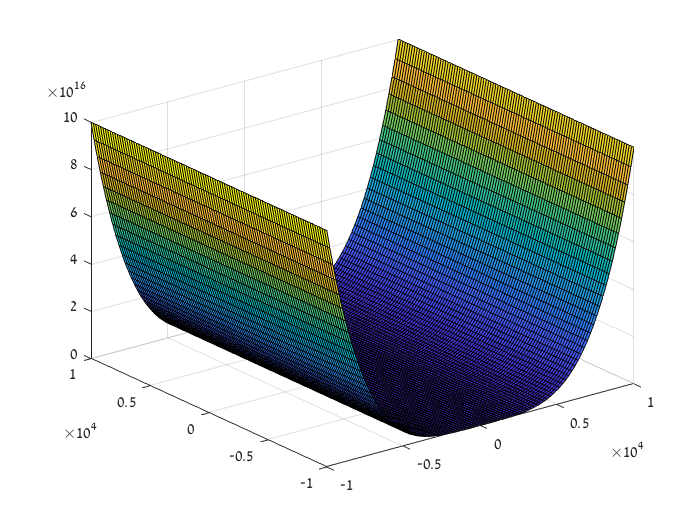

clear
Bounds = [-500 500]; N=10; %plot grid resolution
[x,y]=meshgrid(linspace(Bounds(1),Bounds(2)),linspace(Bounds(1),Bounds(2)));
z=Rosenbrock(x ,y);
surf(x,y,z);

IC = (Bounds(2)-Bounds(1))*rand(5,2)+Bounds(1);

for IC_idx = 1:5
    fprintf('IC:  x =  %.2f y= %.2f \n',IC(IC_idx,1),IC(IC_idx,2))
    [XMin, Emin ,iter_final,output_final] = QN(@Rosenbrock,IC(IC_idx,:));
    fprintf('QN:  x =  %.2f y= %.2f  cost = %.2f \n',XMin(1),XMin(2),Emin)
    [XMin,final_iter,step_size,Emin,eval,cost_change,LOG]  = SteepestDescend(@Rosenbrock,IC(IC_idx,:));
    fprintf('SD  x =  %.2f y= %.2f  cost = %.2f \n',XMin(1),XMin(2),Emin)
    [XMin, Emin, Iter_Num, Eval_Num, last_Step_size, last_change] = Modify_SA( @Rosenbrock , IC(IC_idx,:) ,Bounds);
    fprintf('SA:  x =  %.2f y= %.2f  cost = %.2f \n',XMin(1),XMin(2),Emin)
    [XMin, Emin, Iter_Num, Eval_Num, last_change] = Modify_GA( @Rosenbrock,Bounds);
    fprintf('GA: x =  %.2f y= %.2f  cost = %.2f \n',XMin(1),XMin(2),Emin)
    [XMin, Emin, Iter_Num, Eval_Num, last_Step_size, last_change] = My_Amoeba(@Rosenbrock , IC(IC_idx,:) ,Bounds);
    fprintf('Downhill: x =  %.2f y= %.2f  cost = %.2f \n',XMin(1),XMin(2),Emin)
end

IC:  x =  -4689.93 y= -6888.90 


QN:  x =  -160.36 y= -6887.95  cost = 10629580227.68 


SD  x =  1.98 y= 3.94  cost = 0.00 


SA:  x =  1.34 y= 1.55  cost = 1.11 


GA: x =  1.44 y= 1.36  cost = 5.58 


Downhill: x =  2.00 y= 4.00  cost = 0.00 


IC:  x =  9161.84 y= 6005.45 


QN:  x =  361.43 y= 6006.40  cost = 155318680185.73 


SD  x =  77.50 y= 6005.95  cost = 5699.93 


SA:  x =  66.44 y= 4414.18  cost = 4152.52 


GA: x =  3.76 y= 12.15  cost = 41.21 


Downhill: x =  -65.32 y= 10000.00  cost = 328736632.93 


IC:  x =  4378.07 y= -4200.94 


QN:  x =  150.92 y= -4200.00  cost = 7277282316.13 


SD  x =  1.98 y= 3.90  cost = 0.00 


SA:  x =  2.54 y= 6.22  cost = 0.91 


GA: x =  4.89 y= 24.57  cost = 13.03 


Downhill: x =  -41.95 y= 1760.44  cost = 1936.04 


IC:  x =  5750.68 y= -7260.95 


QN:  x =  206.33 y= -7260.00  cost = 24830520298.62 


SD  x =  1.98 y= 3.91  cost = 0.00 


SA:  x =  2.03 y= 4.13  cost = 0.00 


GA: x =  0.95 y= -0.54  cost = 22.01 


Downhill: x =  -20.86 y= 660.16  cost = 507275.77 


IC:  x =  -1621.40 y= 5571.51 


QN:  x =  -87.83 y= 5572.44  cost = 45881904.56 


SD  x =  74.65 y= 5572.03  cost = 5277.43 


SA:  x =  80.98 y= 6558.93  cost = 6240.78 


GA: x =  0.33 y= -0.79  cost = 10.81 


Downhill: x =  75.50 y= 5701.83  cost = 5439.21 


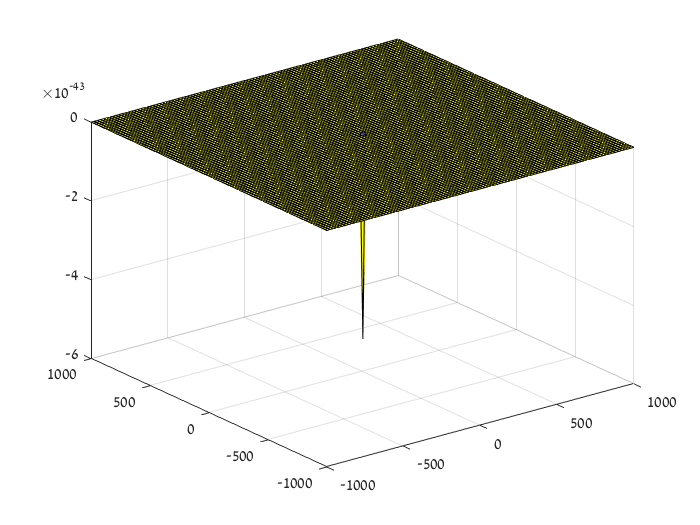

Bounds = [-500 500]; N=10; %plot grid resolution
[x,y]=meshgrid(linspace(Bounds(1),Bounds(2)),linspace(Bounds(1),Bounds(2)));
z=Easom(x ,y);
surf(x,y,z);

IC = (Bounds(2)-Bounds(1))*rand(5,2)+Bounds(1);
for IC_idx = 1:5
    fprintf('IC:  x =  %.2f y= %.2f \n',IC(IC_idx,1),IC(IC_idx,2))
    [XMin, Emin ,iter_final,output_final] = QN(@Easom,IC(IC_idx,:));
    fprintf('QN:  x =  %.2f y= %.2f  cost = %.2f \n',XMin(1),XMin(2),Emin)
    [XMin,final_iter,step_size,Emin,eval,cost_change,LOG]  = SteepestDescend(@Easom,IC(IC_idx,:));
    fprintf('SD  x =  %.2f y= %.2f  cost = %.2f \n',XMin(1),XMin(2),Emin)
    [XMin, Emin, Iter_Num, Eval_Num, last_Step_size, last_change] = Modify_SA( @Easom , IC(IC_idx,:) ,Bounds);
    fprintf('SA:  x =  %.2f y= %.2f  cost = %.2f \n',XMin(1),XMin(2),Emin)
    [XMin, Emin, Iter_Num, Eval_Num, last_change] = Modify_GA( @Easom,Bounds);
    fprintf('GA:  x =  %.2f y= %.2f  cost = %.2f \n',XMin(1),XMin(2),Emin)
    [XMin, Emin, Iter_Num, Eval_Num, last_Step_size, last_change] = My_Amoeba(@Easom , IC(IC_idx,:) ,Bounds);
    fprintf('Downhill: x =  %.2f y= %.2f  cost = %.2f \n',XMin(1),XMin(2),Emin)
end

IC:  x =  474.00 y= -308.32 


QN:  x =  474.00 y= -308.32  cost = 0.00 


SD  x =  474.00 y= -308.32  cost = 0.00 


SA:  x =  -5.74 y= 18.44  cost = -0.00 


GA:  x =  3.41 y= 3.17  cost = -0.90 


Downhill: x =  475.41 y= -309.74  cost = -0.00 


IC:  x =  146.75 y= 402.97 


QN:  x =  146.75 y= 402.97  cost = 0.00 


SD  x =  146.75 y= 402.97  cost = 0.00 


SA:  x =  214.83 y= 425.80  cost = -0.00 


GA:  x =  3.16 y= 3.20  cost = -0.99 


Downhill: x =  148.16 y= 401.55  cost = 0.00 


IC:  x =  -75.73 y= 759.29 


QN:  x =  -75.73 y= 759.29  cost = -0.00 


SD  x =  -75.73 y= 759.29  cost = -0.00 


SA:  x =  -94.72 y= 673.58  cost = -0.00 


GA:  x =  3.05 y= 2.95  cost = -0.94 


Downhill: x =  -74.31 y= 757.87  cost = 0.00 


IC:  x =  422.56 y= 914.42 


QN:  x =  422.56 y= 914.42  cost = -0.00 


SD  x =  422.56 y= 914.42  cost = -0.00 


SA:  x =  400.63 y= 948.57  cost = -0.00 


GA:  x =  3.00 y= 3.22  cost = -0.96 


Downhill: x =  423.98 y= 913.01  cost = -0.00 


IC:  x =  624.08 y= -314.45 


QN:  x =  624.08 y= -314.45  cost = 0.00 


SD  x =  624.08 y= -314.45  cost = 0.00 


SA:  x =  538.29 y= -316.02  cost = -0.00 


GA:  x =  3.24 y= 2.92  cost = -0.92 


Downhill: x =  625.49 y= -315.86  cost = -0.00 


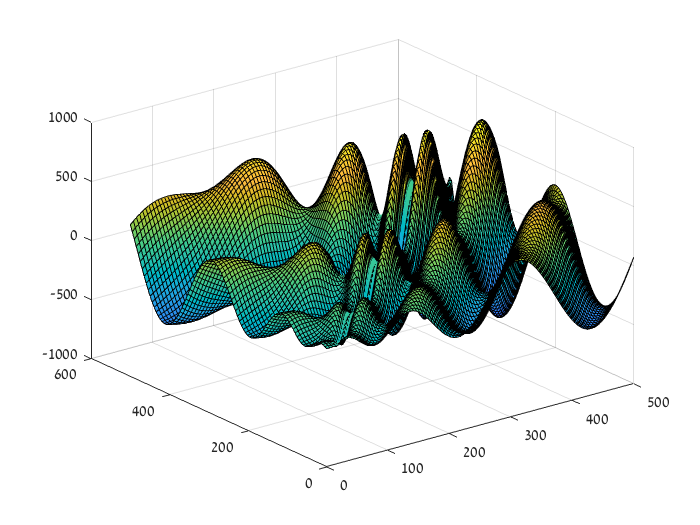

Bounds = [0 500]; N=10; %plot grid resolution
[x,y]=meshgrid(linspace(Bounds(1),Bounds(2)),linspace(Bounds(1),Bounds(2)));
z=Eggholder(x ,y);
surf(x,y,z);

IC = (Bounds(2)-Bounds(1))*rand(5,2)+Bounds(1);

for IC_idx = 1:5
    fprintf('IC:  x =  %.2f y= %.2f \n',IC(IC_idx,1),IC(IC_idx,2))
    [XMin, Emin ,iter_final,output_final] = QN(@Eggholder,IC(IC_idx,:));
    fprintf('QN:  x =  %.2f y= %.2f  cost = %.2f \n',XMin(1),XMin(2),Emin)
    [XMin,final_iter,step_size,Emin,eval,cost_change,LOG]  = SteepestDescend(@Eggholder,IC(IC_idx,:));
    fprintf('SD  x =  %.2f y= %.2f  cost = %.2f \n',XMin(1),XMin(2),Emin)
    [XMin, Emin, Iter_Num, Eval_Num, last_Step_size, last_change] = Modify_SA( @Eggholder , IC(IC_idx,:) ,Bounds);
    fprintf('SA:  x =  %.2f y= %.2f  cost = %.2f \n',XMin(1),XMin(2),Emin)
    [XMin, Emin, Iter_Num, Eval_Num, last_change] = Modify_GA( @Eggholder,Bounds);
    fprintf('GA:  x =  %.2f y= %.2f  cost = %.2f \n',XMin(1),XMin(2),Emin)
    [XMin, Emin, Iter_Num, Eval_Num, last_Step_size, last_change] = My_Amoeba(@Eggholder , IC(IC_idx,:) ,Bounds);
    fprintf('Downhill: x =  %.2f y= %.2f  cost = %.2f \n',XMin(1),XMin(2),Emin)
end

IC:  x =  103.03 y= 158.98 


QN:  x =  97.27 y= 148.10  cost = -250.65 


SD  x =  97.27 y= 148.10  cost = -250.65 


SA:  x =  418.87 y= 208.11  cost = -629.62 


GA:  x =  482.21 y= 469.82  cost = -956.73 


Downhill: x =  97.27 y= 148.10  cost = -250.65 


IC:  x =  118.91 y= 317.95 


QN:  x =  150.23 y= 338.31  cost = -493.96 


SD  x =  150.23 y= 338.31  cost = -493.96 


SA:  x =  17.91 y= 403.10  cost = -425.30 


GA:  x =  480.87 y= 468.58  cost = -955.76 


Downhill: x =  150.23 y= 338.31  cost = -493.96 


IC:  x =  293.63 y= 268.01 


QN:  x =  281.63 y= 274.09  cost = -560.45 


SD  x =  281.63 y= 274.09  cost = -560.45 


SA:  x =  418.79 y= 208.33  cost = -629.62 


GA:  x =  482.58 y= 470.16  cost = -956.82 


Downhill: x =  287.19 y= 274.21  cost = -558.23 


IC:  x =  60.53 y= 115.11 


QN:  x =  97.27 y= 148.10  cost = -250.65 


SD  x =  97.27 y= 148.10  cost = -250.65 


SA:  x =  418.34 y= 207.94  cost = -629.63 


GA:  x =  482.28 y= 469.67  cost = -956.46 


Downhill: x =  97.27 y= 148.10  cost = -250.65 


IC:  x =  494.15 y= 349.69 


QN:  x =  615.08 y= 404.78  cost = -1023.63 


SD  x =  615.08 y= 404.78  cost = -1023.63 


SA:  x =  479.51 y= 467.21  cost = -954.68 


GA:  x =  480.82 y= 468.27  cost = -956.30 


Downhill: x =  418.56 y= 208.04  cost = -629.63 


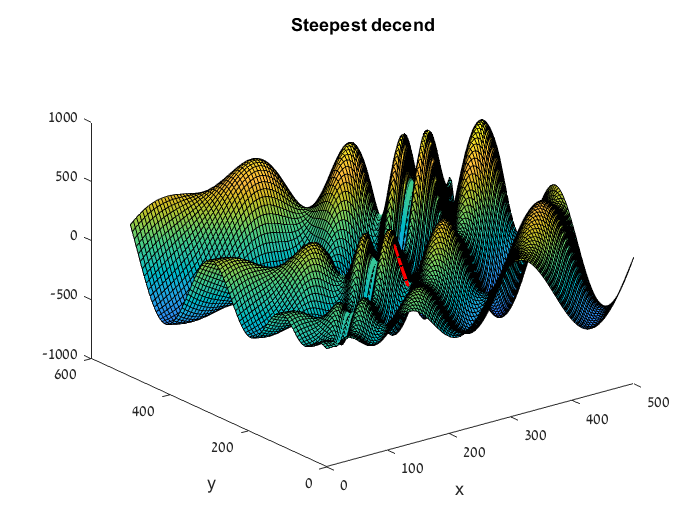


Bounds = [0 500]; N=10; %plot grid resolution
[x,y]=meshgrid(linspace(Bounds(1),Bounds(2)),linspace(Bounds(1),Bounds(2)));
z=Eggholder(x ,y);
figure; hold on;
surf(x,y,z)

IC = (Bounds(2)-Bounds(1))*rand(5,2)+Bounds(1);
[~,~,~,~,~,~,LOG] = SteepestDescend(@Eggholder,IC(1,:));

Z = Eggholder(LOG(:,1),LOG(:,2));
plot3(LOG(:,1),LOG(:,2),Z,'-.r','linewidth',2);
view(3)
xlabel('x'); ylabel('y'); title('Steepest decend');